# ASTE 580 - Homework 3

## Problem** 1**

mu = 1;
r0 = [0;2;0];
v0 = 1/sqrt(2)*[-1;1;0];
h = cross(r0,v0)

h =          0
         0
    1.4142


e = 1/mu*cross(v0,h)-r0/norm(r0)

e =     1.0000
   -0.0000
         0


dot(r0,e) %Rounding error by the computer

ans = -4.4409e-16

syms f;
r = norm(h)^2/(mu * (1+norm(e)*cos(f))) %Using the general formula

$$r = \frac{2}{\cos\left(f\right)+1}$$

r = norm(h)^2/(mu * (2*cos(f/2)^2)) %Using the parabolic formula

$$r = \frac{1}{{\cos\left(\frac{f}{2}\right)}^{2}}$$

f0 = acosd((norm(h)^2/(norm(r0)*mu)-1)/norm(e))

f0 = 90.0000

r = 32;
v = sqrt(norm(v0)^2-2*mu*(1/norm(r0)-1/norm(r)))

v = 0.2500

f = acosd((norm(h)^2/(r*mu)-1)/norm(e))

f = 159.6359

**Answers:**

a. $\vec{h}=[0;0;1.41]$ and $\vec{e}=[1.00;0;0]$

b. $r(f)=\frac{2}{1+cos(f)}=\frac{1}{cos^2\frac{f}{2}}$

c. $f=90^{\circ}$

d. $v = 0.25 \frac{km}{s}$

e. $f=159.64^{\circ}$

## Problem 2

clear all;
mu = 3.986e5;
i_hat = [1;0;0];
j_hat = [0;1;0];
k_hat = [0;0;1];
r = [10000;1000;0];
v = [1;sqrt(mu/10000)+1;1];
epsilon = norm(v)^2/2-mu/norm(r)

epsilon = -11.9187

h = cross(r,v)

h = 1.0e+04 *

    0.1000
   -1.0000
    7.2135


p = norm(h)^2/mu

p = 1.3308e+04

e = 1/mu*cross(v,h)-r/norm(r);
norm(e)

ans = 0.4518

i = acosd(dot(h,k_hat)/norm(h))

i = 7.9314

n = cross(k_hat,h);
Omega = acosd(dot(n,i_hat)/norm(n))

Omega = 5.7106

omega = acosd(dot(n,e)/(norm(n)*norm(e)))

omega = 44.1588

f = acosd(dot(e,r)/(norm(e)*norm(r)))

f = 44.1588

a = - mu/(2*epsilon)

a = 1.6722e+04

n = sqrt(mu/a^3)

n = 2.9198e-04

T = 2*pi*sqrt(a^3/mu) / 3600

T = 5.9776

E = 2*atand(sqrt((1-norm(e))/(1+norm(e)))*tand(f/2))

E = 27.9913

**Answers:**

Orbital elements:

- 
$$a = 16,722 km$$


- 
$$e = 0.45$$


- 
$$i = 7.93^{\circ}$$


- 
$$\Omega = 5.71^{\circ}$$


- 
$$\omega = 44.16^{\circ}$$


- 
$$f_0 = 44.16^{\circ}$$



$$\mathcal{E} = -11.92 J$$



$$\vec{h} = [0.10; -1.00; 7.21]$$



$$n = 0.00029 s$$



$$T = 5.98 hr$$



$$f = 44.16^{\circ}$$



$$E = 27.99^{\circ}$$


## Problem 3

### Part A.1

Substituting $E=iF$ into the equation for eccentiric anomaly we get:


$$tan\frac{iF}{2}=\sqrt{\frac{1-e}{1+e}}tan\frac{f}{2}$$


Multiply through the entire equation by $-i$


$$-itan\frac{iF}{2}=\sqrt{(-1)^3\frac{1-e}{1+e}}tan\frac{f}{2}$$


Using the hyperbolic trig identity $tanh(u)=-itan(iu)$


$$tanh\frac{F}{2}=\sqrt{\frac{e-1}{e+1}}tan\frac{f}{2}$$


### Part A.2

Substituting $E=iF$ into the transcendental equation we get:


$$iF-esin(iF)=\sqrt{\frac{\mu}{a^3}}(t-\tau)$$


Multipy through by $i$


$$-F+e[-isin(iF)]=\sqrt{-\frac{\mu}{a^3}}(t-\tau)$$


Using the hyperbolic trig identity $sinh(u)=-isin(iu)$


$$esinhF-F=\sqrt{\frac{\mu}{|a|^3}}(t-\tau)$$


### Part B

Solve for $F$ when $f=\frac{\pi}{2}$:


$$F=2atanh\sqrt{\frac{e-1}{e+1}}$$


Simplify using the definition of the inverse hyperbolic tangent

$F=ln\sigma$ where $\sigma=\frac{1+\sqrt{\frac{e-1}{e+1}}}{1-\sqrt{\frac{e-1}{e+1}}}$

Simplify $\sigma$


$$\sigma=\frac{\sqrt{e+1}+\sqrt{e-1}}{\sqrt{e+1}-\sqrt{e-1}}=\frac{\sqrt{e+1}+\sqrt{e-1}}{\sqrt{e+1}-\sqrt{e-1}}*\frac{\sqrt{e+1}+\sqrt{e-1}}{\sqrt{e+1}+\sqrt{e-1}}=e+\sqrt{e+1}\sqrt{e-1}$$



$$\sigma=e+\sqrt{e^2-1}$$


Plug $\sigma$ back into the equation for $F$


$$F=ln(e+\sqrt{e^2-1})$$


Plug $F$ into the transcendental equation. Due to symmetry, we know that it should take the same amount of time to sweep from $-\frac{\pi}{2}$ to $0$ and from $0$ to $\frac{\pi}{2}$. 


$$\sqrt{\frac{\mu}{|a|^3}}\Delta t = 2[esinh(ln(e+\sqrt{e^2-1}))-ln(e+\sqrt{e^2-1})$$


Simplify using the definition of the hyperbolic sine $sinh(u)=\frac{e^u-e^{-u}}{2}$


$$\sqrt{\frac{\mu}{|a|^3}}\Delta t = 2[e\sqrt{e^2-1}-ln(e+\sqrt{e^2-1})]$$


Solve for $\Delta t$


$$\Delta t=2\sqrt{\frac{\mu}{|a|^3}}[e\sqrt{e^2-1}-ln(e+\sqrt{e^2-1})]$$


## Problem 4

### Part A

Take the derivative of $r^2\dot{\theta}=H$


$$2\dot{r}\dot{\theta}+r^2\ddot{\theta}=0$$


This shows that $r\ddot{\theta}+2\dot{r}\dot{\theta}=0$ can be integrated once to find that $r^2\dot{\theta}=H$

### Part B

Substitute $\dot{\theta}=\frac{H}{r^2}$


$$\ddot{r}=\frac{H^2}{r^3}-\frac{\mu}{r^2}$$


Take the derivative of $U=-\frac{H^2}{2r^2}+\frac{\mu}{r}$


$$\frac{\partial U}{\partial r}=\frac{H}{r^3}-\frac{\mu}{r^2}$$


This shows that $\ddot{r}=\frac{\partial U}{\partial r}$

## Problem 5

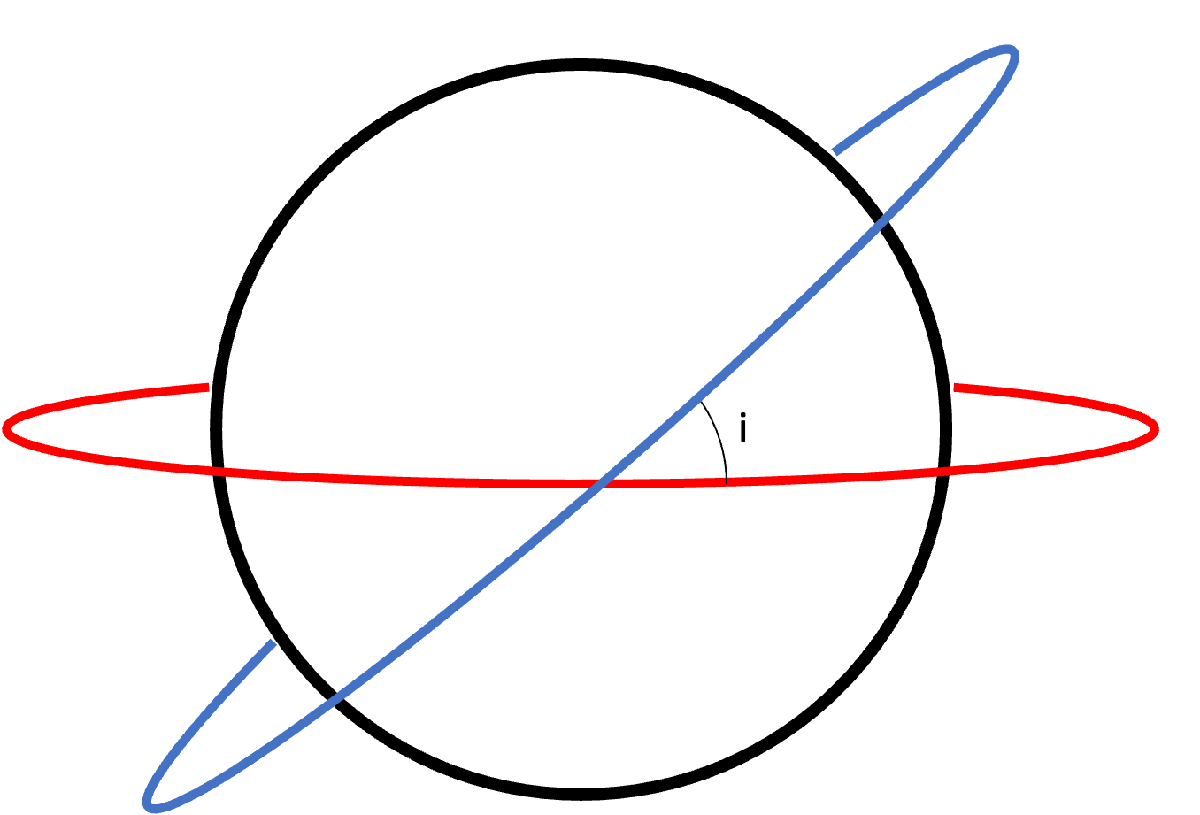

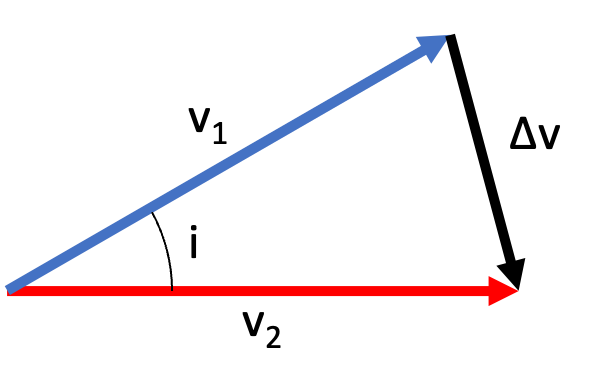

Since $v_1=v_2$ we can divide the equilatoral triangle into two identical right triangles and use the law of sines to get


$$\frac{\frac{\Delta v}{2}}{sin\frac{i}{2}}=\frac{v_1}{sin\frac{\pi}{2}}$$


Solve for $\Delta v$


$$\Delta v=2v_1sin\frac{i}{2}$$


Substitute $v_1=\sqrt{\frac{\mu}{r_1}}$


$$\Delta v=2\sqrt{\frac{\mu}{r_1}}sin\frac{i}{2}$$
